# MECH 320 Finite Element Method Project

## Introduction

Modelling this 

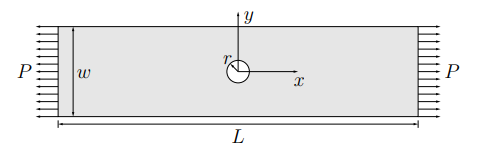

and this

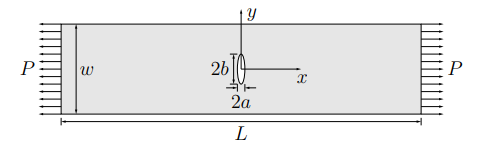

## Results

First we build the model to show the plate geometry and generated mesh

clc
clear all
close all

%% 1: Model parameters
half_crack_height = 6.5;       % Half crack height (mm)
half_crack_width = 1;        % Half crack width (mm)
half_width = 38/2;              % Plate half width (mm)
half_length = 240/2;             % Plate half length (mm)
youngs_modulus = 200*10^3;          % Youngs Modulus of material (MPa)
poissons_ratio = 0.3;          % Poissons ration of material

surf_traction = 10;           % Surface traction (N/mm)
mesh_size = half_crack_height/6; % Mesh refinement (no need to change)

plot_scale_factor = 1;       % Scale factor for plotting deformations, adjust it to be able to visualize contraction of the plate near the hole


% Vector representing rectangular plate geometry
plate = [3 4 -half_length half_length half_length -half_length -half_width -half_width half_width half_width]';

% Vector representing circular or elliptical hole geometry
hole = [1 0 0 half_crack_height]';
hole = [hole;zeros(length(plate)-length(hole),1)];

% Define geometry description matrix (GDM) as a subtraction operation between hole and bar
gdm = [plate, hole];                   % Form the GDM containing all the shapes
names = char('bar','hole')';          % Give names to shapes
geom = decsg(gdm,'bar - hole',names); % Boolean subtraction of hole from bar

%% 3: FEM model (no need to modify this section)
model = createpde('structural','static-planestress');

% Create geometry and include it into the structural model
geometryFromEdges(model,geom);

% Specify material properties
structuralProperties(model,'YoungsModulus',youngs_modulus,'PoissonsRatio',poissons_ratio);

% Apply boundary conditions
structuralBC(model,'Edge',3,'XDisplacement',0);
structuralBC(model,'Vertex',3,'YDisplacement',0);
structuralBoundaryLoad(model,'Edge',1,'SurfaceTraction',[surf_traction;0]);

% Generate mesh
generateMesh(model,'Hmax',mesh_size);

% Solve system of equations
sol = solve(model);

%% 4: Plotting

figure
tiledlayout(3,1)
% Geometry
nexttile          % Create figure
pdegplot(model); % Plot model geometry
axis equal       % Set equal scales for x and y axes
title('Plate Geometry');    % Plot title

% Mesh
nexttile
pdemesh(model); % Plot model mesh
axis equal    % Set equal scales for x and y axes
title('Plate Mesh');   % Plot title

%Mesh Close up
nexttile
pdemesh(model); % Plot model mesh
xlim([-20 0]);
ylim([-15 15]);
title('Plate Mesh Close-up');   % Plot title

Then we find the stress and displacement distribution created by the applied load P

% Von Mises stress contours
svon = 0.5.*sqrt((sol.Stress.sxx-sol.Stress.syy).^2+(0-sol.Stress.sxx).^2+6*(sol.Stress.sxy).^2);   % Calculate von Mises stress

figure                                         % Create figure
pdeplot(model,'XYData',svon,'ColorMap','jet'); % Plot xy data (in this case the von Mises stress)
axis equal                                     % Set equal scales for x and y axes
title('Von Mises Stress Plot');                     % Plot title

% Deformed shape
figure                                         % Create figure
pdeplot(model,"XYData",sol.Displacement.x,"Deformation",sol.Displacement,"DeformationScaleFactor",plot_scale_factor,"ColorMap","jet"); % Plot xy data (in this case displacement and deformation superimposed)
axis equal                                     % Set equal scales for x and y axes
title('Deformation Plot');                    % Plot title

The stress concentration factor is defined as follows for a bar with a hole:


$$\sigma_{\max } =K\sigma_o =K\;\frac{F}{A}=K\;\frac{P\;t}{\left(w-2a\right)t}=K\;\frac{P}{\left(w-2a\right)}$$


We can solve for the stress concentration factor in terms of values obtained through the problem definition and the model


$$K=\sigma_{\max } \frac{\left(w-2a\right)}{P}$$


We can use theoretical method employed in the Photoelasticity lab to find the theoretical nominal and max stresses. Both calculations are shown below.

%% 5: Calculate stress concentration factor

p = [-100,0];                         % Coordinates of point far away from the hole
snom = interpolateStress(sol,p').xx; % Nominal stress x obtained at point far away from hole

smax = max(sol.Stress.sxx)  ;      % Maximum normal stress x in the plate
k_fem = smax/snom;
r = half_crack_width;
theta = pi/2;
snom_thoery = surf_traction/(2*half_width); 
s_r = 0.5*snom_thoery*((1+3-4)*cos(2*theta)); %radial stress at top of hole
s_theta = 0.5*snom_thoery*((1+1)-(1+3)*cos(2*theta)); %tangential stress at top of hole
t_rtheta = -0.5*snom_thoery*(1-3+2)*sin(2*theta); %shear stress at top of hole

smax_theory = s_r*cos(theta)^2+s_theta*sin(theta)^2-2*t_rtheta*sin(theta)*cos(theta);

k_theory = smax_theory/snom_thoery;

%photo elasticity data from 162.75N applied to bar with hole
snom_photo = 0.75; %photoelasticy nominal stress [MPa]
smax_photo = 3.04; %photoelasticy max stress [MPa] ie. stress at edge of hole

k_photo = smax_photo/snom_photo;

fprintf("k_model = %d\nk_theory=%d\nk_photo=%d\n",k_fem,k_theory,k_photo);               % Print k to the console

k_model = 3.480600e+00
k_theory=3
k_photo=4.053333e+00


### Eliptical Hole

Similarly, the stress distribution and displacement magnitudes can be calculated for an eliptical hole with the dimensions shown below.

clc
clear all
close all

%% 1: Model parameters
half_crack_height = 6.5;     % Half crack height (mm)
half_crack_width = 1;        % Half crack width (mm)
half_width = 38/2;           % Plate half width (mm)
half_length = 240/2;         % Plate half length (mm)
youngs_modulus = 200*10^3;   % Youngs Modulus of material (MPa)
poissons_ratio = 0.3;        % Poissons ration of material

surf_traction = 10;              % Surface traction (N/mm)
mesh_size = half_crack_height/6; % Mesh refinement (no need to change)

plot_scale_factor = 1;       % Scale factor for plotting deformations, adjust it to be able to visualize contraction of the plate near the hole


% Vector representing rectangular plate geometry
plate = [3 4 -half_length half_length half_length -half_length -half_width -half_width half_width half_width]';

% Vector representing circular or elliptical hole geometry
hole = [4 0 0 half_crack_width half_crack_height]';
hole = [hole;zeros(length(plate)-length(hole),1)];

% Define geometry description matrix (GDM) as a subtraction operation between hole and bar
gdm = [plate, hole];                   % Form the GDM containing all the shapes
names = char('bar','hole')';          % Give names to shapes
geom = decsg(gdm,'bar - hole',names); % Boolean subtraction of hole from bar

%% 3: FEM model (no need to modify this section)
model = createpde('structural','static-planestress');

% Create geometry and include it into the structural model
geometryFromEdges(model,geom);

% Specify material properties
structuralProperties(model,'YoungsModulus',youngs_modulus,'PoissonsRatio',poissons_ratio);

% Apply boundary conditions
structuralBC(model,'Edge',3,'XDisplacement',0);
structuralBC(model,'Vertex',3,'YDisplacement',0);
structuralBoundaryLoad(model,'Edge',1,'SurfaceTraction',[surf_traction;0]);

% Generate mesh
generateMesh(model,'Hmax',mesh_size);

% Solve system of equations
sol = solve(model);

%% 4: Plotting

figure
tiledlayout(3,1)
% Geometry
nexttile          % Create figure
pdegplot(model); % Plot model geometry
axis equal       % Set equal scales for x and y axes
title('Plate Geometry');    % Plot title

% Mesh
nexttile
pdemesh(model); % Plot model mesh
axis equal    % Set equal scales for x and y axes
title('Plate Mesh');   % Plot title

%Mesh Close up
nexttile
pdemesh(model); % Plot model mesh
xlim([-20 0]);
ylim([-15 15]);
title('Plate Mesh Close-up');   % Plot title

Again, select the stresses and compute the Von Mises stress distribution, and the deformed shape of the bar.

% Von Mises stress contours
svon = 0.5.*sqrt((sol.Stress.sxx-sol.Stress.syy).^2+(0-sol.Stress.sxx).^2+6*(sol.Stress.sxy).^2);   % Calculate von Mises stress

figure                                         % Create figure
pdeplot(model,'XYData',svon,'ColorMap','jet'); % Plot xy data (in this case the von Mises stress)
axis equal                                     % Set equal scales for x and y axes
title('Von Mises Stress');                     % Plot title

% Deformed shape
figure                                         % Create figure
pdeplot(model,"XYData",sol.Displacement.x,"Deformation",sol.Displacement,"DeformationScaleFactor",plot_scale_factor,"ColorMap","jet"); % Plot xy data (in this case displacement and deformation superimposed)
axis equal                                     % Set equal scales for x and y axes
title('Plate Deformation');                    % Plot title

Finally, the stress concentration factor is computed and compared with the theoretical value. This time however, the theoretical stress concentration factor is computed using the formula provided in the lab manual:


$$K=1+2\left( \frac{a}{b} \right)$$
 

where $a$ and $b$ are the half minor and half major axis of the elipse respectively.

%% 5: Calculate stress concentration factor
p = [-100,0];                                   % Coordinates of point far away from the hole
snom = interpolateStress(sol,p').xx;            % Nominal stress x obtained at point far away from hole
smax = max(sol.Stress.sxx);                     % Maximum normal stress x in the plate
k_theory = 1+2*(half_crack_height/half_crack_width);   % Stress concentration factor for ellipse
k_fem    = smax/snom;
fprintf("snom = %d\nsmax = %d\nk_theory = %d\nk_fem = %d\n", snom, smax, k_theory, k_fem);

snom = 1.000003e+01
smax = 7.751193e+01
k_theory = 14
k_fem = 7.751166e+00


This exact procedure is repeated for an ellipse with $a=3$ and $a=6$ to compare stress concentration factors. First, $a=3$:

clc
clear all
close all

%% 1: Model parameters
half_crack_height = 6.5;     % Half crack height (mm)
half_crack_width = 3;        % Half crack width (mm)
half_width = 38/2;           % Plate half width (mm)
half_length = 240/2;         % Plate half length (mm)
youngs_modulus = 200*10^3;   % Youngs Modulus of material (MPa)
poissons_ratio = 0.3;        % Poissons ration of material

surf_traction = 10;              % Surface traction (N/mm)
mesh_size = half_crack_height/6; % Mesh refinement (no need to change)

plot_scale_factor = 1;       % Scale factor for plotting deformations, adjust it to be able to visualize contraction of the plate near the hole


% Vector representing rectangular plate geometry
plate = [3 4 -half_length half_length half_length -half_length -half_width -half_width half_width half_width]';

% Vector representing circular or elliptical hole geometry
hole = [4 0 0 half_crack_width half_crack_height]';
hole = [hole;zeros(length(plate)-length(hole),1)];

% Define geometry description matrix (GDM) as a subtraction operation between hole and bar
gdm = [plate, hole];                   % Form the GDM containing all the shapes
names = char('bar','hole')';          % Give names to shapes
geom = decsg(gdm,'bar - hole',names); % Boolean subtraction of hole from bar

%% 3: FEM model (no need to modify this section)
model = createpde('structural','static-planestress');

% Create geometry and include it into the structural model
geometryFromEdges(model,geom);

% Specify material properties
structuralProperties(model,'YoungsModulus',youngs_modulus,'PoissonsRatio',poissons_ratio);

% Apply boundary conditions
structuralBC(model,'Edge',3,'XDisplacement',0);
structuralBC(model,'Vertex',3,'YDisplacement',0);
structuralBoundaryLoad(model,'Edge',1,'SurfaceTraction',[surf_traction;0]);

% Generate mesh
generateMesh(model,'Hmax',mesh_size);

% Solve system of equations
sol = solve(model);

%% 5: Calculate stress concentration factor
p = [-100,0];                                   % Coordinates of point far away from the hole
snom = interpolateStress(sol,p').xx;            % Nominal stress x obtained at point far away from hole
smax = max(sol.Stress.sxx);                     % Maximum normal stress x in the plate
k_theory = 1+2*(half_crack_height/half_crack_width);   % Stress concentration factor for ellipse
k_fem    = smax/snom;
fprintf("snom = %d\nsmax = %d\nk_theory = %d\nk_fem = %d\n", snom, smax, k_theory, k_fem);

snom = 1.000007e+01
smax = 5.605128e+01
k_theory = 5.333333e+00
k_fem = 5.605090e+00


Finally $a=6$:

clc
clear all
close all

%% 1: Model parameters
half_crack_height = 6.5;     % Half crack height (mm)
half_crack_width = 6;        % Half crack width (mm)
half_width = 38/2;           % Plate half width (mm)
half_length = 240/2;         % Plate half length (mm)
youngs_modulus = 200*10^3;   % Youngs Modulus of material (MPa)
poissons_ratio = 0.3;        % Poissons ration of material

surf_traction = 10;              % Surface traction (N/mm)
mesh_size = half_crack_height/6; % Mesh refinement (no need to change)

plot_scale_factor = 1;       % Scale factor for plotting deformations, adjust it to be able to visualize contraction of the plate near the hole


% Vector representing rectangular plate geometry
plate = [3 4 -half_length half_length half_length -half_length -half_width -half_width half_width half_width]';

% Vector representing circular or elliptical hole geometry
hole = [4 0 0 half_crack_width half_crack_height]';
hole = [hole;zeros(length(plate)-length(hole),1)];

% Define geometry description matrix (GDM) as a subtraction operation between hole and bar
gdm = [plate, hole];                   % Form the GDM containing all the shapes
names = char('bar','hole')';          % Give names to shapes
geom = decsg(gdm,'bar - hole',names); % Boolean subtraction of hole from bar

%% 3: FEM model (no need to modify this section)
model = createpde('structural','static-planestress');

% Create geometry and include it into the structural model
geometryFromEdges(model,geom);

% Specify material properties
structuralProperties(model,'YoungsModulus',youngs_modulus,'PoissonsRatio',poissons_ratio);

% Apply boundary conditions
structuralBC(model,'Edge',3,'XDisplacement',0);
structuralBC(model,'Vertex',3,'YDisplacement',0);
structuralBoundaryLoad(model,'Edge',1,'SurfaceTraction',[surf_traction;0]);

% Generate mesh
generateMesh(model,'Hmax',mesh_size);

% Solve system of equations
sol = solve(model);

%% 5: Calculate stress concentration factor
p = [-100,0];                                   % Coordinates of point far away from the hole
snom = interpolateStress(sol,p').xx;            % Nominal stress x obtained at point far away from hole
smax = max(sol.Stress.sxx);                     % Maximum normal stress x in the plate
k_theory = 1+2*(half_crack_height/half_crack_width);   % Stress concentration factor for ellipse
k_fem    = smax/snom;
fprintf("snom = %d\nsmax = %d\nk_theory = %d\nk_fem = %d\n", snom, smax, k_theory, k_fem);

snom = 1.000014e+01
smax = 3.641877e+01
k_theory = 3.166667e+00
k_fem = 3.641827e+00


## Discussion of Results

## Concluding Remarks

## References